# T2-06. Getting the CPSDM from data through Welch estimator

## Introduction

In this tutorial you will learn how to estimate the CPSDM of a random process from a multivariate time series through the Welch estimator. 

The dataset employed in this tutorial is '*datasets/dataset_02_VAR_2V*', which includes a synthetic 2-variate zero mean time series generated with a restricted VAR(5) model, and the true spectrum of the VAR model. This allows comparison between the estimated CPSDM and the true CPSDM. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

N_f     = 500;      % number of elements of the frequency vector

N_seg   = 8;       % Number of segments in which the time series is divided.
                    % Leave empty [] for default value (see function
                    % 'fun_default_value').

overlap = 0.5;     % fraction of segment that is overlapped. 0.5 is for 50%.
                    % Leave empty [] for default value (see function
                    % 'fun_default_value').

window_name = 'Hamming';    % Name of the window applied to the segments.
                            % For a list of window names, see function
                            % 'initialise_window'. 
                            % Leave empty [] for default value (see function
                            % 'fun_default_value').

% %%% Plot parameters
font_size         = 18;
figure_position_1 = [0 0 1000 400];
figure_position_2 = [0 0 1000 800];
CC                = colororder;
color_estimated   = CC(5,:);
color_true        = CC(4,:);
color_fmin        = CC(1,:);

Load from the dataset the data (in the form of a `data` object) and the true CPSDM (in the form of a CPSDM object) of the related VAR model. For details related to the fields of these objects, see functions `initialise_data` and `initialise_CPSDM`.

load dataset_02_VAR_2V data_VAR CPSDM_VAR 

Have a look at the time series considered. 

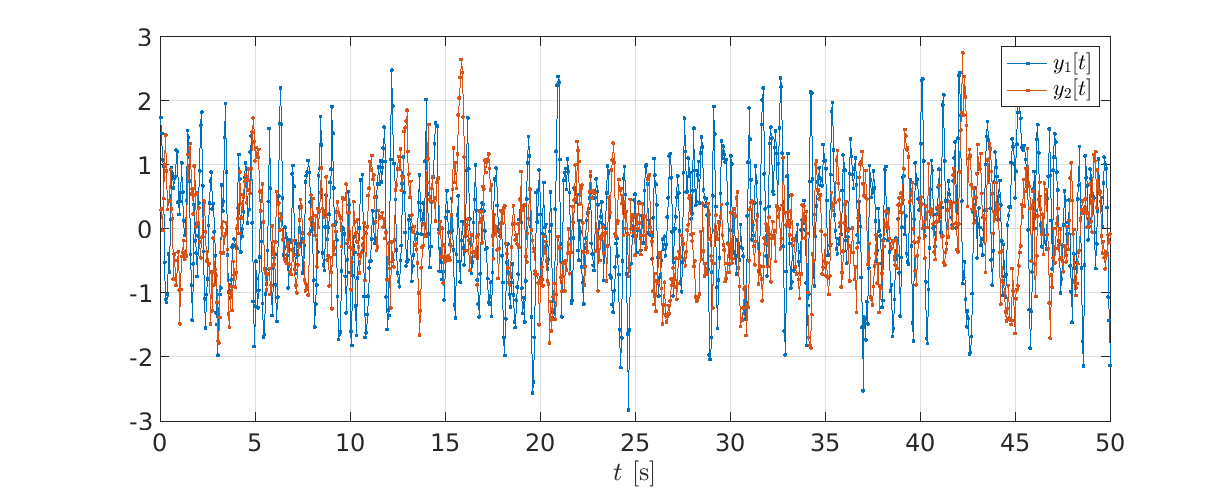

figure

x = data_VAR.x_values;
y = data_VAR.y_values;
plot(x,y,'.-')

grid on
xlabel('$t$ [s]','Interpreter','latex')
xlim([0 data_VAR.x_values(end)])
legend('$y_1[t]$','$y_2[t]$','interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position_1)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum, `f_vector`, will be defined within this frequency range.

delta_t     = data_VAR.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_VAR.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = linspace(f_min,f_max,N_f);

Initialise a CPSDM object  with the fields required by function `get_CPSDM_data_Welch`. 

CPSDM0 = initialise_CPSDM('x_values', f_vector);

Initialise a `window` object with the fields required by function `get_CPSDM_data_Welch`.

window = initialise_window('name',window_name);

Compute the CPSDM of the data.

[CPSDM_Welch] = get_CPSDM_data_Welch(data_VAR, CPSDM0, N_seg, overlap, window);

Plot the obtained CPSDM together with the true spectrum. Remark on the minimum frequency, $f_{min}$, higher than the value obtained above based on $t_{sim}$ (see first element of f_vector), because with Welch method the minimum frequency is based on the duration of the segments. Note also that the cross spectrum is, in general, complex valued. Thus, first plot is for real part (co-spectrum), and second plot is for imaginary part (quad-spectrum).

k = CPSDM_Welch.k;



fprintf('\n CPSDM estimation for %d segments, %.1f%% overlap\n',N_seg,100*overlap);


 CPSDM estimation for 8 segments, 50.0% overlap


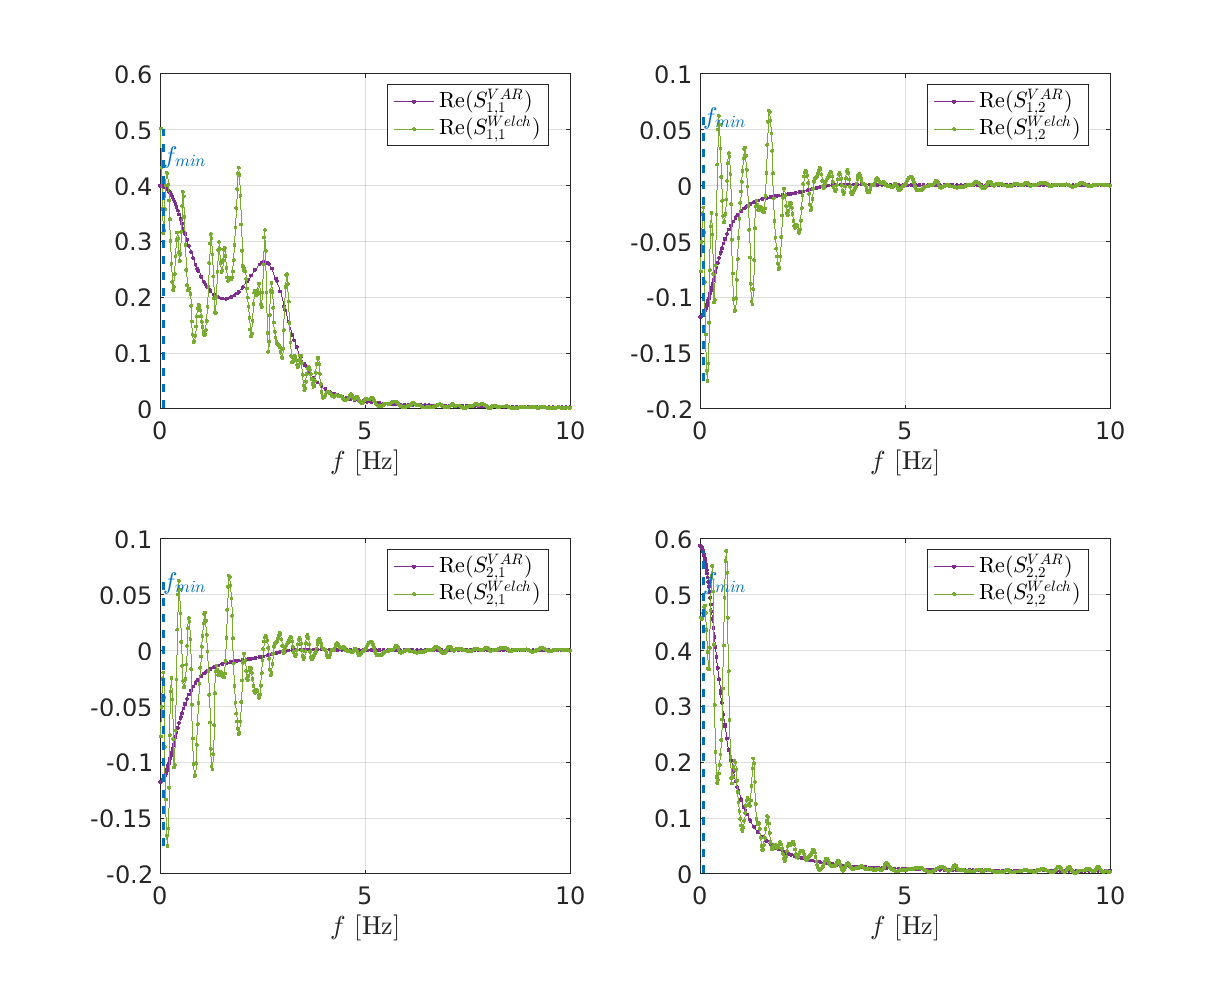




% Co-spectrum

figure(1)

for ii = 1:k

    for jj = 1:k

        subplot(k,k,(ii-1)*k+jj)

        x = CPSDM_VAR.x_values;
        y = real(squeeze(CPSDM_VAR.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_true)

        hold on

        x = CPSDM_Welch.x_values;
        y = real(squeeze(CPSDM_Welch.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_estimated)

        x_min = CPSDM_Welch.x_parameters.x_min;
        y_min = min(y);
        y_max = max(y);
        plot([x_min x_min],[y_min y_max ],'--','color',color_fmin,'LineWidth',2)
        text(1.05*x_min,0.9*y_max,'$f_{min}$',...
        'color',color_fmin,...
        'fontsize',font_size,...
        'Interpreter','latex')
    
        leg_VAR = sprintf('Re$(S^{VAR}_{%d,%d})$',ii,jj);
        leg_Welch = sprintf('Re$(S^{Welch}_{%d,%d})$',ii,jj);
        legend({leg_VAR,leg_Welch},...
               'Interpreter','latex',...
               'Location','best')

        grid on
        xlabel('$f$ [Hz]','Interpreter','latex')
        set(gca,'fontsize',font_size)

    end

end

set(gcf,'position',figure_position_2)

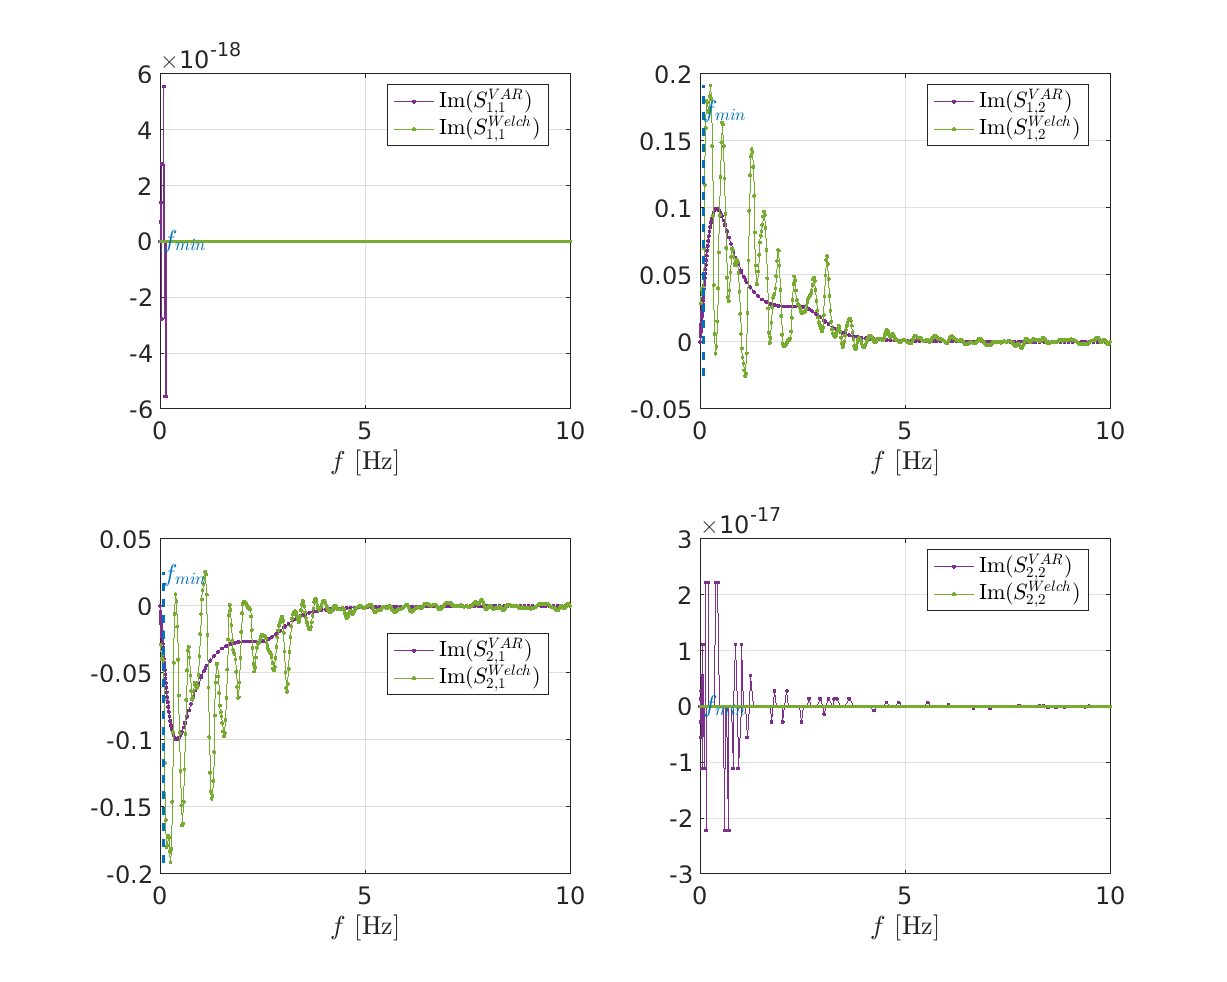



% Quad-spectrum

figure(2)

for ii = 1:k

    for jj = 1:k

        subplot(k,k,(ii-1)*k+jj)

        x = CPSDM_VAR.x_values;
        y = imag(squeeze(CPSDM_VAR.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_true)

        hold on

        x = CPSDM_Welch.x_values;
        y = imag(squeeze(CPSDM_Welch.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_estimated)

        x_min = CPSDM_Welch.x_parameters.x_min;
        y_min = min(y);
        y_max = max(y);
        plot([x_min x_min],[y_min y_max ],'--','color',color_fmin,'LineWidth',2)
        text(1.05*x_min,0.9*y_max,'$f_{min}$',...
        'color',color_fmin,...
        'fontsize',font_size,...
        'Interpreter','latex')

        leg_VAR = sprintf('Im$(S^{VAR}_{%d,%d})$',ii,jj);
        leg_Welch = sprintf('Im$(S^{Welch}_{%d,%d})$',ii,jj);
        legend({leg_VAR,leg_Welch},...
               'Interpreter','latex',...
               'Location','best')

        grid on
        xlabel('$f$ [Hz]','Interpreter','latex')
        set(gca,'fontsize',font_size)

    end

end

set(gcf,'position',figure_position_2)

## Remarks

- Note that the `CPSDM` is obtained by computing each auto/cross spectrum $S_{ij}$ through function `get_S_data_Welch`. You can refer to remarks detailed in tutorial '*getting_S_from_data_through_Welch'* for further insights on this method.